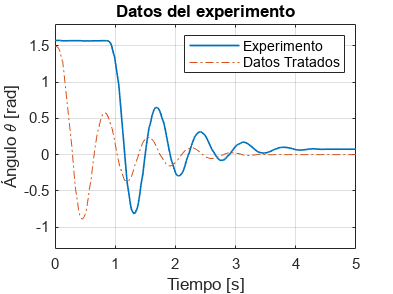

%Datos originales
load("PruebaData.mat")
Tiempo = Tiempo - Tiempo(1);

% Se cargan los datos obtenidos experimentalmente
load("FrictionCoef.mat")

time1Vvista = [time1; (linspace(time1(end),5,100))'];
theta1Vvista = [theta1; theta1(end)*ones(100,1)];

%Comparativa Datos obtenidos vs tratados
figure()
plot(Tiempo,Datos*pi/180,"LineWidth",1);
hold on
plot(time1Vvista,theta1Vvista,"-.");
hold off
title('Datos del experimento')
xlim([0,5])
ylim([-1.3,1.8])
xlabel('Tiempo [s]')
ylabel('Ángulo \theta [rad]')
grid("on")
legend('Experimento', 'Datos Tratados')

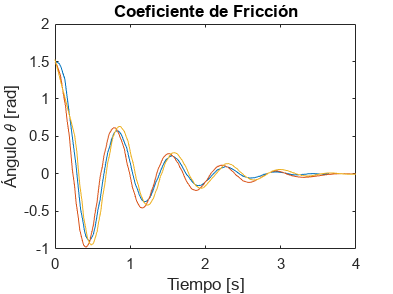


% Se gráfican estos datos
figure()
plot(time1,theta1);
hold on
plot(time2,theta2);
plot(time3,theta3);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

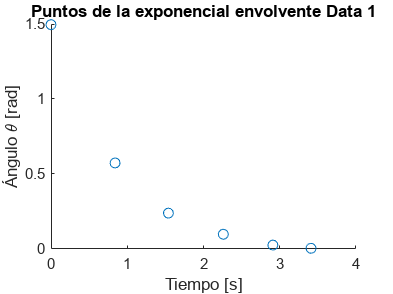


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks1p,locs1p] = findpeaks(theta1,time1);
[pks1n,locs1n] = findpeaks(-theta1,time1);
pks1 = [theta1(1,1); pks1p];
locs1 = [time1(1,1); locs1p];


%Se gráfican los picos
figure()
scatter(locs1,pks1);
title('Puntos de la exponencial envolvente Data 1')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

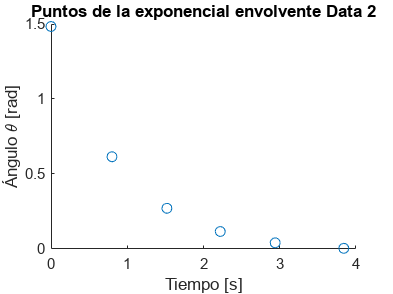


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks2p,locs2p] = findpeaks(theta2,time2);
[pks2n,locs2n] = findpeaks(-theta2,time2);
pks2 = [theta2(1,1); pks2p];
locs2 = [time2(1,1); locs2p];

%Se gráfican los picos
figure()
scatter(locs2,pks2);
title('Puntos de la exponencial envolvente Data 2')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

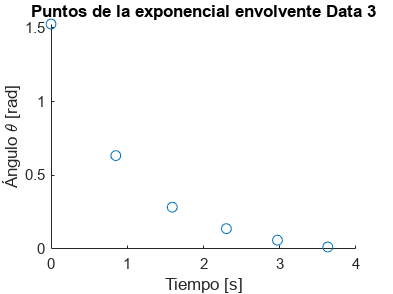



%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks3p,locs3p] = findpeaks(theta3,time3);
[pks3n,locs3n] = findpeaks(-theta3,time3);
pks3 = [theta3(1,1); pks3p];
locs3 = [time3(1,1); locs3p];

%Se gráfican los picos
figure()
scatter(locs3,pks3);
title('Puntos de la exponencial envolvente Data 3')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')


envolvente1 = @(t) ((pi/2)*exp(-1.25*t))

envolvente1 = function_handle with value:
    @(t)((pi/2)*exp(-1.25*t))


envolvente2 = @(t) ((pi/2)*exp(-1.15*t))

envolvente2 = function_handle with value:
    @(t)((pi/2)*exp(-1.15*t))


envolvente3 = @(t) ((pi/2)*exp(-1.14*t))

envolvente3 = function_handle with value:
    @(t)((pi/2)*exp(-1.14*t))


time = linspace(0,4,1000);

e1 = envolvente1(time);
e2 = envolvente2(time);
e3 = envolvente3(time);


% Se gráfican las funciones obtenidas
figure()
plot(time1,theta1,'LineWidth',1);
hold on
plot(time,e1,'r-.');
plot(time,-e1,'r-.');
hold off
tit = title('Friction Coefficient - \beta Parameter')

tit =   Text (Friction Coefficient - \beta Parameter) with properties:

                 String: 'Friction Coefficient - \beta Parameter'
               FontSize: 11
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [2.0000 2.0257 1.4211e-14]
                  Units: 'data'

  Show all properties


xl = xlabel('Time [s]')

xl =   Text (Time [s]) with properties:

                 String: 'Time [s]'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [2.0000 -2.2555 -1.0000]
                  Units: 'data'

  Show all properties


grid on
xlim([0,4])
yl = ylabel('Angular Position \theta [rad]')

yl =   Text (Angular Position \theta [rad]) with properties:

                 String: 'Angular Position \theta [rad]'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-0.2848 1.9073e-06 -1.0000]
                  Units: 'data'

  Show all properties


lgd = legend('Experimental Data', '\theta (t) = \pm \pi/2 \cdot e^-^\beta ^\cdot ^t', 'Location','southeast')

lgd =   Legend (Experimental Data, \theta (t) = \pm \pi/2 \cdot e^-^\beta ^\cdot ^t) with properties:

         String: {'Experimental Data'  '\theta (t) = \pm \pi/2 \cdot e^-^\beta ^\cdot ^t'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6170 0.1359 0.2696 0.0926]
          Units: 'normalized'

  Show all properties


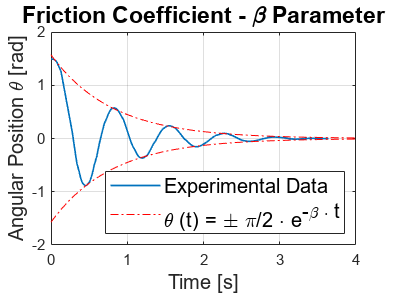

fontsize(lgd,12,'points')
fontsize(yl,12,'points')
fontsize(xl,12,'points')
fontsize(tit,14,'points')


$$$$


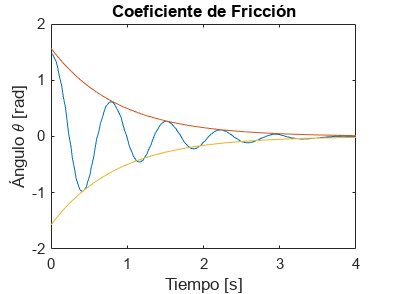


figure()
plot(time2,theta2);
hold on
plot(time,e2);
plot(time,-e2);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

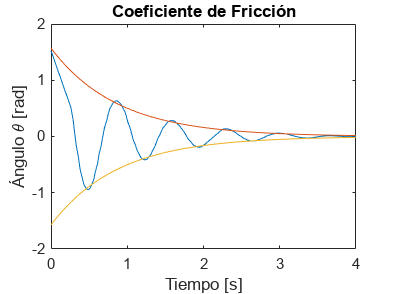


figure()
plot(time3,theta3);
hold on
plot(time,e3);
plot(time,-e3);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

## Gráfica Final

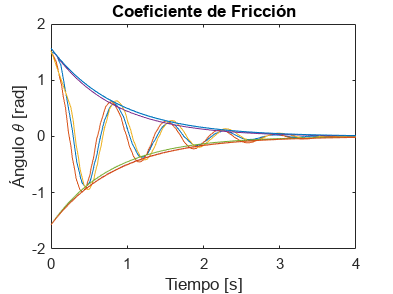

figure()
plot(time1,theta1);
hold on
plot(time2,theta2);
plot(time3,theta3);
plot(time,e1);
plot(time,-e1);
plot(time,e2);
plot(time,-e2);
plot(time,e3);
plot(time,-e3);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

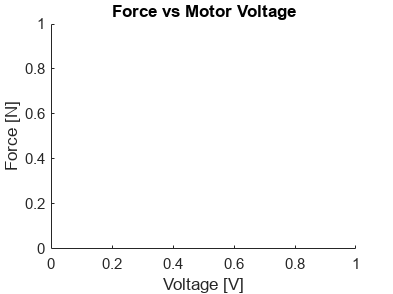

figure()
title(['Force vs Motor Voltage'])
xlabel('Voltage [V]')
ylabel('Force [N]')

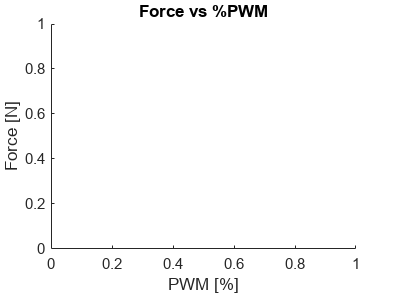


figure()
title('Force vs %PWM')
xlabel('PWM [%]')
ylabel('Force [N]')

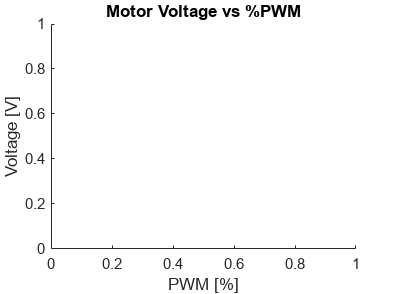


figure()
title('Motor Voltage vs %PWM')
ylabel('Voltage [V]')
xlabel('PWM [%]')